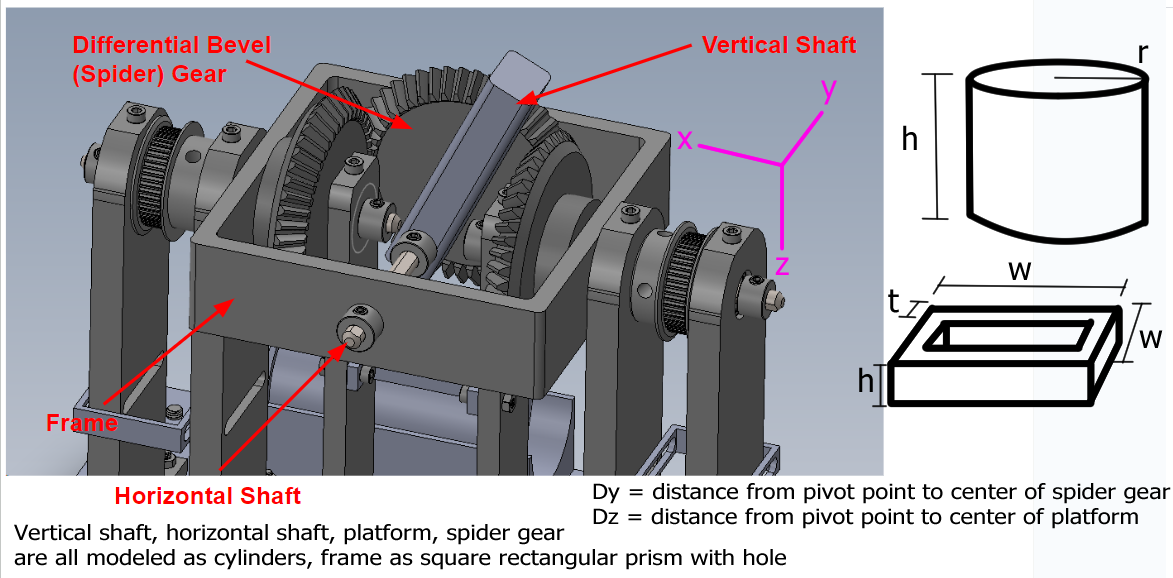

% Mass, radius, and height for the frame, horizontal shaft, vertical shaft, platform, and differential bevel gear
m = [15.74/1000, (239.54/1000), (3.77/1000), 2.72155, (11.592/1000)];  % [kg]
r = [0, (7.5/1000), (10/1000), (7/39.37), ((73/2)/1000)];  % [kg]
h = [(30/1000), (170/1000), ((50+15)/1000), (.25/39.37), (8/1000)];  % [m]
% width of the frame
w1 = (120/1000);  % [m]
% thickness of the frame
t1 = (4.43/1000);  % [m]
% distance from center of mass to origin for platform
dz4 = (15+50+(.25*25.4))/1000;  % [m]
% distance from center of mass to origin for differential bevel gear
dy5 = (73/2)/1000;  % [m]

% useful mass values for calculating moments of intertia for the frame
mt = ((2*w1*t1)/( (w1^2) - (w1-2*t1)^2))*m(1);
ms = m(1)-mt;

% X, Y, and Z moments of inertia for the differential system
IxxL = [((ms/12)*( ((w1-2*t1)^2) + (h(1))^2)) + ((mt/12)*((t1^2)+(h(1)^2)+(((w1-t1)/2)^2))), ...
         (m(2)/12)*((3*(r(2)^2))+(h(2)^2)), (m(3)/12)*((3*(r(3)^2))+(h(3)^2))+(m(3)*((h(3)/2)^2)), ...
         ((m(4)/12)*((3*(r(4)^2))+(h(4)^2)))+(m(4)*(dz4^2)), ((m(5)/12)*((3*(r(5)^2))+(h(5)^2)))+(m(5)*(dy5^2))];

IyyL = [((ms/12)*( ((w1-2*t1)^2) + (h(1))^2)) + ((mt/12)*((t1^2)+(h(1)^2)+(((w1-t1)/2)^2))), ...
         ((m(2)/2)*(r(2))^2), (m(3)/12)*((3*(r(3)^2))+(h(3)^2))+(m(3)*((h(3)/2)^2)), ...
         ((m(4)/12)*((3*(r(4)^2))+(h(4)^2)))+(m(4)*(dz4^2)), ((m(5)/2)*(r(5))^2)];

IzzL = [(m(1)/12)*( (2*(w1^2)) - (2*(w1 - (2*(t1)))^2) ), ...
         (m(2)/12)*((3*(r(2)^2))+(h(2)^2)), ((m(3)/2)*(r(3))^2), ...
         ((m(4)/2)*(r(4))^2), ((m(5)/12)*((3*(r(5)^2))+(h(5)^2)))+(m(5)*(dy5^2))];

Ixx = IxxL(1)+IxxL(2)+IxxL(3)+IxxL(4)+IxxL(5);  % [kg*m^2]
Iyy = IyyL(1)+IyyL(2)+IyyL(3)+IyyL(4)+IyyL(5);  % [kg*m^2]
Izz = IzzL(1)+IzzL(2)+IzzL(3)+IzzL(4)+IzzL(5);  % [kg*m^2]

% intertia tensor for the differential system (products of inertia are 0 so
% this is the principle coordinate system)
J = [Ixx, 0, 0;
     0, Iyy, 0;
     0, 0, Izz];

J =     0.0360         0         0
         0    0.0354         0
         0         0    0.0436
